# Modelo de presa-depredador con Holling tipo I, II, III

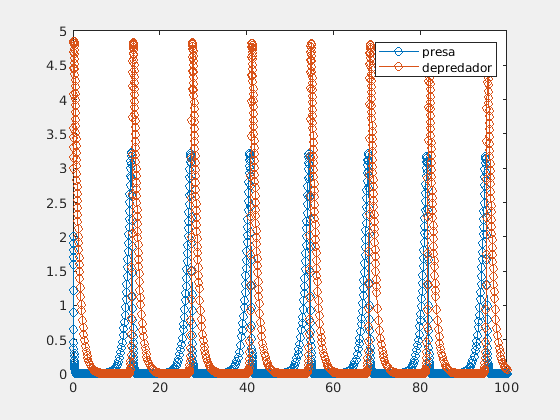

global alpha beta gamma lambda K

alpha = 1; 
beta = 2;
gamma = 3;
lambda = 1;
K = 10;

f = @(t,x)[alpha*x(1)-beta*x(1)*x(2);
            gamma*x(2)*x(1) - lambda*x(2)];

ode45(f,[0 100],[2 3])
legend("presa", "depredador")

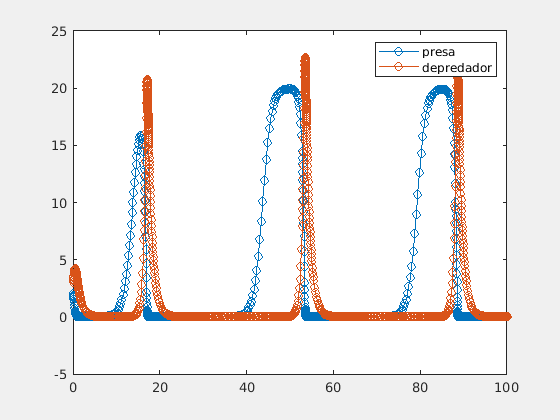



f = @(t,x)[alpha*x(1)*(1-x(1)/K)-beta*x(1)*x(2)/(1+x(1));
            gamma*x(1)*x(2)/(1+x(1)) - lambda*x(2)];

ode45(f,[0 100],[2 3])
legend("presa", "depredador")

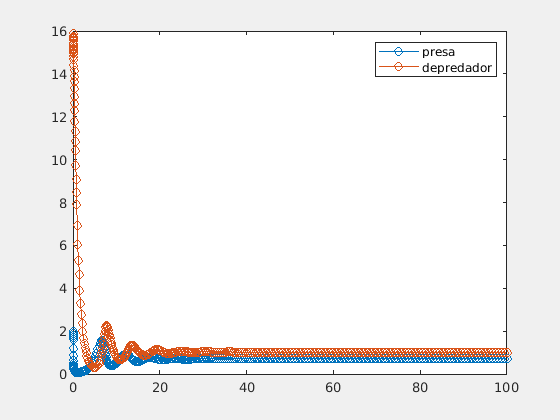


f = @(t,x)[alpha*x(1)*(1-x(1)/K)-beta*x(1)^2*x(2)/(1+x(1)^2);
            gamma*x(1)^2*x(2)/(1+x(1)^2) - lambda*x(2)];

ode45(f,[0 100],[2 15])
legend("presa", "depredador")

# Modelo de huesped parásito con capacidad de carga

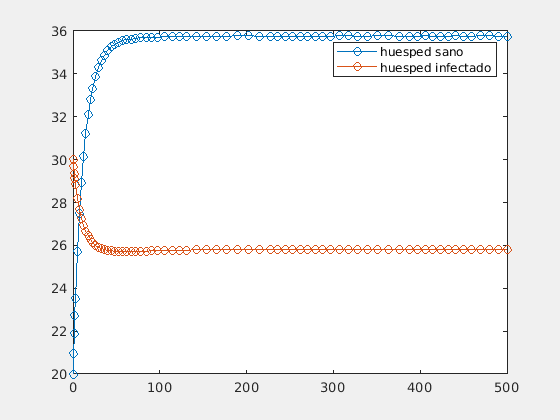

global bn r b a d K

bn = 0.01;
r = 0.1;
a = 0.08;
b = 0.2;
d = 0.06;
K = 80;

f = @(t,x)[bn*x(1)*(1-x(1)/K)+(1-r)*b*x(2)*(1-x(2)/K)-a*x(1)*x(2)/(x(1)+x(2))-d*x(1);
           r*b*x(2)*(1-x(2)/K)+a*x(1)*x(2)/(x(1)+x(2))-d*x(2)];

options = odeset('NonNegative',1:2);
ode45(f,[0 500],[20 30], options)
legend("huesped sano", "huesped infectado")

# Modelo de colonización de parches

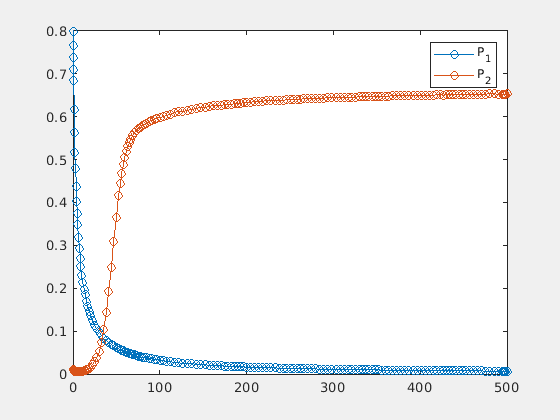

global c1 c2 m1 m2

c1 = 0.3;
c2 = 0.3;
m1 = 0.3;
m2 = 0.1;

f = @(t,x) [c1*x(1)*(1-x(1))-m1*x(1);
            c2*x(2)*(1-x(1)-x(2))-m2*x(2)-c1*x(1)*x(2)];


options = odeset('NonNegative',1:2);
ode45(f,[0 500],[0.8 0.01], options)
legend("P_1", "P_2")

# Metapoblaciones de presa-depredador con capacidad de carga del depredador

Las presas se dividen en dos parches y el depredador puede interactuar con ambos parches

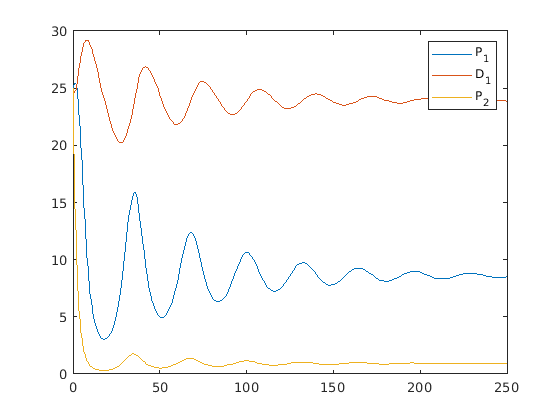

global a1 a2 b1 d1 d2 m12 m21 

a1 = 1;
a2 = 0.8;
b1 = 0.04;
c1 = 0.01;
c2 = 0.01;
d1 = 0.04;
d2 = 0.05;
m12 = 0.05;
m21 = 0.07;
K = 50;

f = @(t,x)[a1*x(1)-d1*x(1)*x(2)-m12*x(1)+m21*x(3);
           c1*x(1)*x(2)*(1-x(2)/K)-c2*x(3)*x(2)*(1-x(2)/K) - b1*x(2);
           a2*x(3)-d2*x(3)*x(2)+m12*x(1)-m21*x(3);
           ];
figure
options = odeset('NonNegative',1:3);
[t,y] = ode45(f,[0 250],[25 25 25],options);
plot(t,y)
legend("P_1","D_1", "P_2")